# **Data Representation & Analysis Assignment 2**

# **ACT Air Quality Analysis Project - Ruhan Shafi**

Air Quality Index (AQI) rating provides accurate and reliable data on the level of pollutants in the air in an environment. The primary use of the AQI is to serve as an indication of how clean the air is at a given time. This data is used for a multitude of purposes by a wide audience. The two most common users of this dataset are scientists and government officials. Some examples of use cases of this data set are for studying how bushfires can affect the air quality, and finding out which pollutant has the largest effect on air quality. However, this is not to say that AQI is strictly used by scientists and government officials, AQI ratings are frequently used by members of the public. For example, AQI ratings are used by people who are suffering from hayfever or asthma to determine how much pollen is in the air and if they need to consider that. 

The formula used by the ACT Deparment of Health is the following:


$$\mathrm{AQI}\;\mathrm{Pollutant}=\frac{\mathrm{polltantat}\;\mathrm{data}\;\mathrm{reading}}{\mathrm{standard}}\times 100$$


This process is done for each of the pollutant and then an average is assagined 

### Project Goal:

The goal of this project is to create a data story using the incomplete data gathered from the ACT Air Quality Monitoring data that is publicly available on the ACT Health Portal. This will be achieved by first, preprocessing the data, by filtering and cleaning the dataset, then analysis to answer questions will be conducted and lastly, informed recommendations will be made backed up by the data given by the project.

## **Processing Data**

**Importing Data Set into Mathlab**

rawdata = readtable("Air_Quality_Monitoring_Data.csv");

This command will import the dataset will into the Mathlab Live Script environment and store it under the variable Name "rawdata"

%head(rawdata)

Should you want to display a preview of the Unedited table, uncomment the command above by removing the percentage sign before the command

rawdata = sortrows(rawdata,'DateTime');

This command sorts data into choronlogical order

rawdata = unique(rawdata);

This command removes any duplicate entries from the dataset to ensure that all the data is valid.

**Cleaning Data**

% Fill missing data
cData = fillmissing(rawdata,"linear","DataVariables",@isnumeric);

**Removing Abnormal Data**

cData = removevars(cData,"AQI_PM2_5");

The column "AQI_PM2_5" needs to remove since the cleaning algorithm generates irrational numbers in that particular column. If this column is not removed then it can cause problems with data analysis down the track. Another benefit to removing this data is freeing up additional processing power.

**Labling the AQI**

entries = size(cData,1);
AQI_Label = cell(entries,1);

for rating = 1:entries
    aqi = cData.AQI_Site(rating);

    if aqi >= 200
        AQI_Label(rating) = {'Hazardous'};
    elseif aqi >= 150
        AQI_Label(rating) = {'Very Poor'};
    elseif aqi >= 100
        AQI_Label(rating) = {'Poor'};
    elseif aqi >= 67
        AQI_Label(rating) = {'Fair'};
    elseif aqi >= 34
        AQI_Label(rating) = {'Good'};
    else 
        AQI_Label(rating) = {'Very Good'};
    end
end

cData = addvars(cData,AQI_Label);

The purpose of this script is to go through the dataset and assign an AQI rating for each data entry using the AQI_Site value, and the label is entered into the dataset under a new column.

**Removing Redunate Data**

cData= removevars(cData,["Time","Date",]);

This command removes the last 2 columns and their associated data since it is duplicated content found in the column "DateTime". By removing these datasets, additional processing power is freed up

**Coverting time into 24 Hour Format & Mathlab Format**

cData.DateTime.Format = "dd-MMM-uuuu HH:mm:ss";

This command converts the data in column "`DateTime`" from a string into a timestamp format which enables Mathlab to use this data for time-related operations such as creating timetables or calendars

**Converting Table into Timetable **

timedata = table2timetable(cData);

This command generates a timetable using the data from `"cData"`.This is done by taking the timestamp generated from the last command and using it as the ordering system.

**Finding timerange of data**

[tmin,tmax]= bounds(timedata.DateTime)

tmin = datetime
   01-Jan-2012 07:00:00


tmax = datetime
   23-Aug-2020 12:00:00


[aqimin,aqimax]= bounds(timedata.AQI_Site)

aqimin = 0

aqimax = 996

avgAqi = mean(timedata.AQI_Site)

avgAqi = 39.8527

The purpose of this section of code is to determine some critical information for this dataset. The first command creates two variables that outline the first Timestamp recorded being `01-Jan-2012 07:00:00` and the last recorded Timestamp being `23-Aug-2020 12:00:00`. Using this information gathered, a vital piece of the data story is revealed, that being the period of the data collection. As stated above, the data gathered here was collected throughout 8 and a half years. 

The second command is similar to the first command, this command creates two variables that outline the highest and lowest AQI value. And the last command simply finds the mean of the AQI 

**Dividing the Data by Location**

cividx = timedata.Name == "Civic";
monidx = timedata.Name == "Monash";
floidx = timedata.Name == "Florey";

v1=sum(cividx);
v2=sum(monidx);
v3=sum(floidx);

CivicData = timedata(cividx,:);
MonashData = timedata(monidx,:);
FloreyData = timedata(floidx,:);

## **Brief explanation of AQI**

## **Metadata Table of Contents **

**Name:**

The name of the Monitoring Station

There are 3 Monitoring Stations in Canberra, ACT: Monash, Civic & Florey

**GPS**:

The exact coordinates of the Monitoring Stations and which sensor recorded the reader, there are 9 unqiue GPS coordinates throughout the dataset

**DataTime:**

The Exact Data and Time of when the data was recorded

**NO2:**

Stands for Nitrogen Dioxide, a highly reactive greenhouse gas, 

**03:**

Stands for Ozone, an unstable, highly reactive gas that this critical to filter out damaging ultraviolet radiation from the sun. However it is also critical that we maintain a fine balance of Ozone, this is since if there is too much Ozone in that atmosphere, it will raise the global temperature. This concept is at the forefront of Global warming.

**PM2.5/10**

Stands for particulate matter with the 2.5/10 referring to its relative size of 2.5/10 microns or smaller, for reference, one strand of human hair is 50 microns. Rather than being one singular chemical pollutant, PM is rather a classification of small solid particles and liquid droplets suspended in the air. These pollutants are dangerous to human health because they bypass many of our body’s defences due to their small size meaning that the immune system can't detect them. These pollutants are difficult to track due to their varying sources and they can be made up of numerous types of chemicals and particles, and they can be partly liquid, as opposed to solid, like a common dust particle. This also helps to contribute to their ability of bypass the immune system

**AQI Values:**

These are the AQI Values of the different pollutants, that are calculated with the formula shown at the front of the report.

## **Data Analysis**

**Data distrubation**

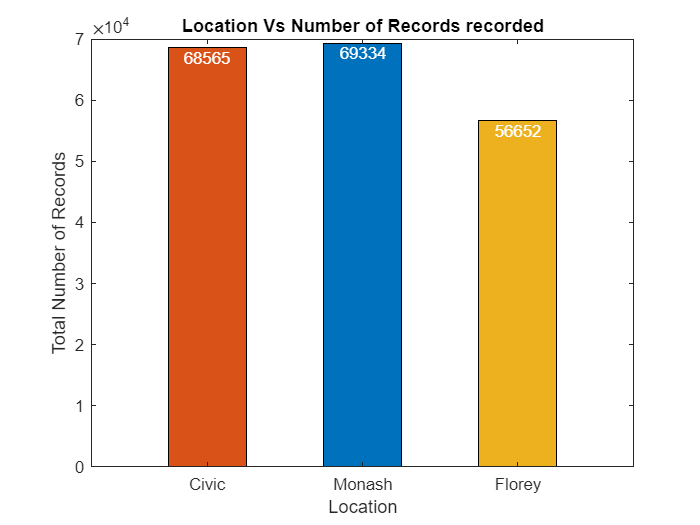

x = categorical({'Civic','Monash','Florey'});
x = reordercats(x,{'Civic','Monash','Florey'});
y = [v1  v2  v3];
la = bar(x,y,0.5,'FaceColor','flat');
xlabel("Location","FontSize",11)
ylabel("Total Number of Records","FontSize",11)
title("Location Vs Number of Records recorded","FontSize",11)
xtips1 = la(1).XEndPoints;
ytips1 = la(1).YEndPoints;
labels1 = string(la(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','top','Color',"W")
la.CData(1,:) = [0.8500 0.3250 0.0980];
la.CData(3,:) = [0.9290 0.6940 0.1250];

One of the most noticeable trends with the data distribution amongst the different locations is that Florey has significantly fewer data recorded compared to the other locations. This is because when the ACT AQI monitoring program started in 2012, there were only two monitoring points and it wasn't until February of 2014 that the Florey monitoring point was installed, as evident by the data below, following this, the monitoring point continued to work alongside the other two points until the data cut off point of August 2020. This means that Florey's data is less reliable compared to the data that was gathered from the other stations due to the smaller amount of data collected.

[ftmin,ftmax]= bounds(FloreyData.DateTime)

ftmin = datetime
   25-Feb-2014 17:00:00


ftmax = datetime
   23-Aug-2020 12:00:00


**Caterogaizing the data**

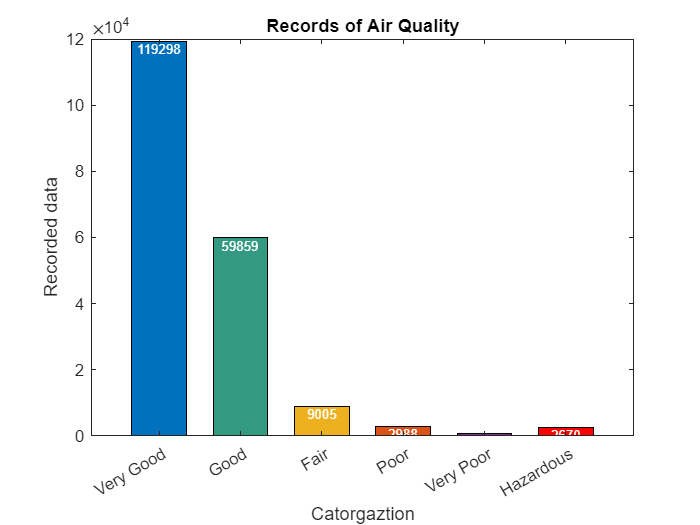

verygoodaqi = timedata.AQI_Label == "Very Good";
goodaqi = timedata.AQI_Label == "Good";
fairaqi = timedata.AQI_Label == "Fair";
pooraqi = timedata.AQI_Label == "Poor";
verypooraqi = timedata.AQI_Label == "Very Poor";
hazardousaqi = timedata.AQI_Label == "Hazardous";

sumvgaqi = sum(verygoodaqi);
sumgaqi = sum(goodaqi);
sumfaqi = sum(fairaqi);
sumpaqi = sum(pooraqi);
sumvpaqi = sum(verypooraqi);
sumhaqi = sum(hazardousaqi);

tablex = categorical({'Very Good','Good','Fair','Poor','Very Poor','Hazardous'});
tablex = reordercats(tablex,{'Very Good','Good','Fair','Poor','Very Poor','Hazardous'});
tabley = [sumvgaqi  sumgaqi  sumfaqi  sumpaqi  sumvpaqi  sumhaqi];
la2 = bar(tablex,tabley,0.675,'FaceColor','flat');
title("Records of Air Quality")
ylabel("Recorded data");
xlabel("Catorgaztion");
xtips1 = la2(1).XEndPoints;
ytips1 = la2(1).YEndPoints;
labels1 = string(la2(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment', 'top', 'Color', "W", "FontSize", 8)

la2.CData(2,:) = [.2 .6 .5];
la2.CData(3,:) = [0.9290 0.6940 0.1250];
la2.CData(4,:) = [0.8500 0.3250 0.0980];
la2.CData(5,:) = [0.4940 0.1840 0.5560];
la2.CData(6,:) = [1 0 0];

This graph showing the amount of data in each category outlines an anomaly in an otherwise normal downward trend. This is because the Hazardous Rating has far more entries in the dataset compared to Very Poor. This can largely be attributed to the bushfires, more notably, the 2019-2020 bushfire season. This is because whilst Canberra didn't experience any bushfires, large fires were happening in NSW that fall, close to the border of Canberra. Some of the closest fires were less than 50 km away from Canberra's borders. The reason why bushfire seasons such as the 2019-2020 bushfire season can have such a large impact on the air quality is that it releases pollutants into the atmosphere. Some of the pollutants that are released are carbon dioxide, ozone, Nitrogen Dixoide and more. All of these chemicals plays are large part in determining the air quality. This is because the AQI is calculated using the amount of pollutants verse the standard amount. It is important to note, that there weren't any major fires in Canberra during the AQI Monitoring period. This helps to eliminate the possibility of any local fires contributing to creating a low air quality. This means that the cause of most of the Hazardous ratings can be attributed to Canberra's surroundings, rather than Canberra. The reason why there were more recordings of Hazardous rating was that fires would go out of control quickly and stay in the Hazardous rating for extended periods. Sometimes up to the entirety of the bushfire season. 

**Creating Civic Data**

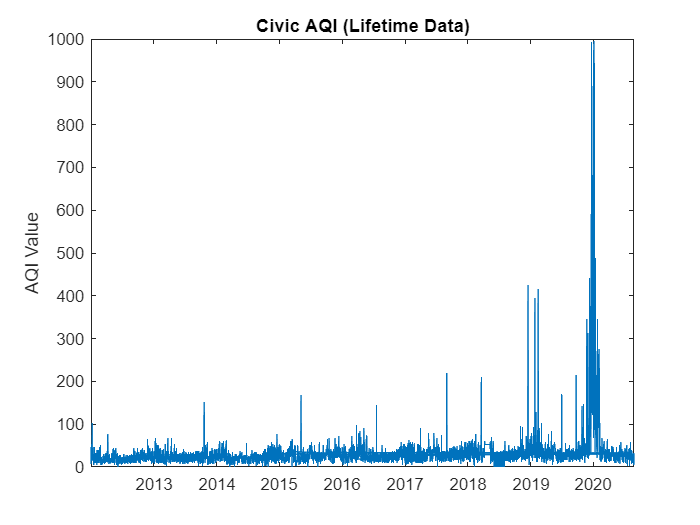

plot(CivicData.DateTime,CivicData.AQI_Site,"LineWidth",0.01)
title("Civic AQI (Lifetime Data)")
ylabel("AQI Value")

**Creating Data Data**

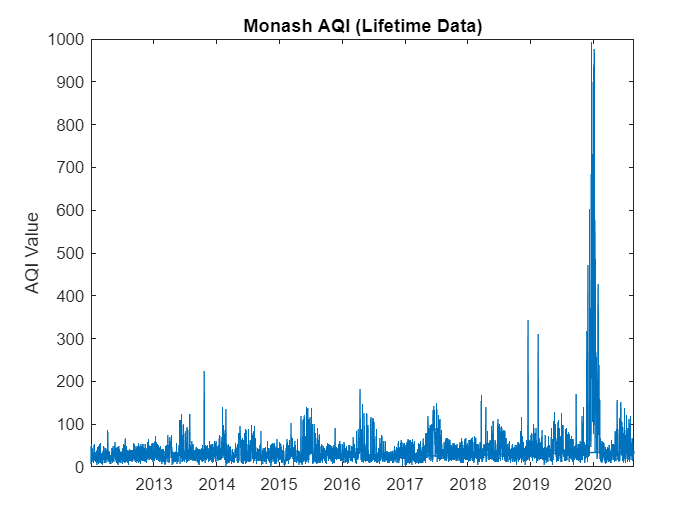

plot(MonashData.DateTime,MonashData.AQI_Site,"LineWidth",0.01)
title("Monash AQI (Lifetime Data)")
ylabel("AQI Value")

**Creating Florey Data**

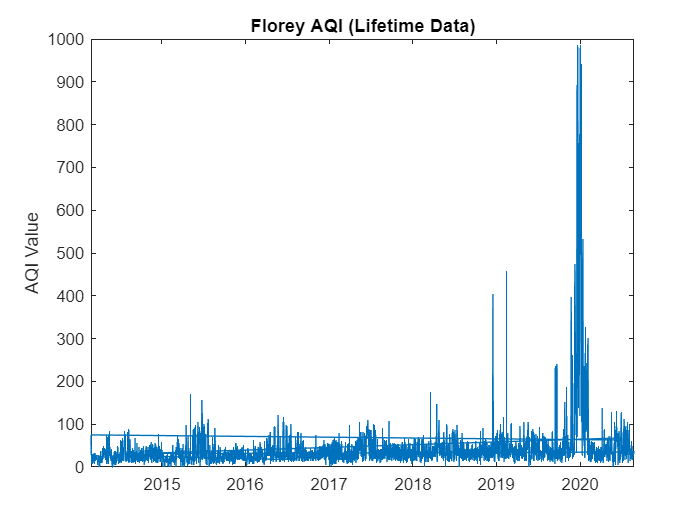

plot(FloreyData.DateTime,FloreyData.AQI_Site,"LineWidth",0.01)
title("Florey AQI (Lifetime Data)")
ylabel("AQI Value")

One of the most noticeable trends between all of the graphs is the spike in the AQI Rating during 2020. This spike can also largely be attributed to the 2019-2020 bushfires. As stated before, during the bushfires, pollutants would be emitted from the fires that negatively affect air quality and these pollutants travel from the site of the fire outwards using the wind. Some of these pollutants find their way to Canberra as evident from these graphs.

**Average AQI for each Location vs Canberra's Average AQI**

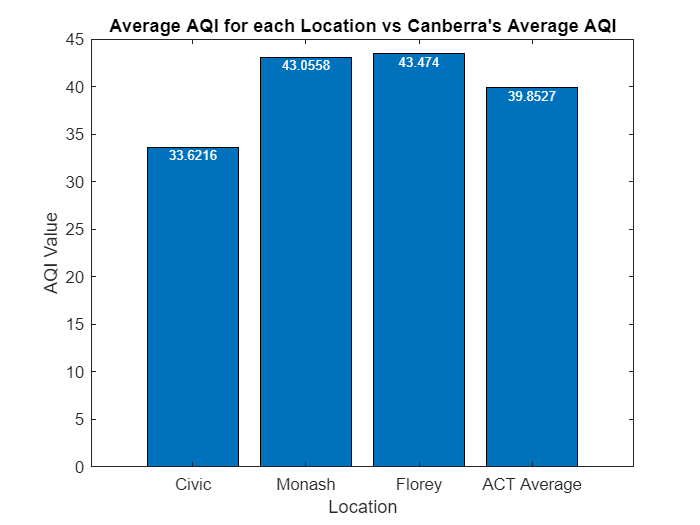

civicaqiav = mean(CivicData.AQI_Site);
monsahaqiav = mean(MonashData.AQI_Site);
floreyaqiav =  mean(FloreyData.AQI_Site);

aqitablex = categorical({'Civic','Monash','Florey','ACT Average'});
aqitablex = reordercats(aqitablex,{'Civic','Monash','Florey','ACT Average'});
aqitabey = [civicaqiav  monsahaqiav  floreyaqiav  avgAqi];
la3 = bar(aqitablex,aqitabey);
title("Average AQI for each Location vs Canberra's Average AQI");
xlabel("Location");
ylabel("AQI Value");
xtips2 = la3(1).XEndPoints;
ytips2 = la3(1).YEndPoints;
labels1 = string(la3(1).YData);
text(xtips2,ytips2,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment', 'top', 'Color', "W", "FontSize", 8)
la3.CData(1,:) = [0.8500 0.3250 0.0980];

One of the noticeable trends in this graph is the fact that Civic has a significantly lower Average AQI rating compared to the other two monitoring stations. This goes against popular thought that Civic would have a large average due to increased traffic from people travelling to and from work in a centralized location compared to the other locations which are primarily residential suburbs. However, this appears not to be the case, why? First of all, it is important to note, that the amount of people using cars to commute to Civic is decreasing due to the tram system in Gungahlin and improved public transport, due to government incentivisation such as Park and Ride, which allows people to park their cars away from Civic and catch the bus. This helps reduce pollutant emissions from vehicles in Civic, however, this doesn't apply in residential suburbs where the other two monitoring stations are.

Another thing to consider, this the geological location of the different monitoring stations, it is important to note that the Monash & Florey monitoring locations are near the edges of Canberra whilst the Civic monitoring is located in the centre of Canberra. This means that during the Bushfire seasons in NSW, the pollutants created by the fires travel by air outwards, then it stands to reason that it will pass through the monitoring stations closer to the borders before reaching the Civic monitoring station. This helps explain why the AQI average is lower in Civic.

## **Discussion & Recommendations**

### **How did the fires stay burning for so long?**

It has been established that the primary cause of the anomaly in the AQI values is due to out of control bushfires. But why is this the case? The answer lies in climate change. Since the global temperature is rising, causing the polar ice caps to melt, it is bringing more intense inclement weather. The main impact on wildlands is more severe and longer-lasting droughts. These droughts cause more of the vegetation to become dried out or to die, this poses a fire risk. However, due to the amplified droughts, the amount of fuel for the fire is at uncontrollable amounts, thus leading to the great displays of nature's fury that are seen on TV come the fire season. As stated before, wildfires release pollutants into the atmosphere that has a drastic effect on not only the local Air Quality but the greater Air Quality of the region. The primary long term problem is that due to the trees burning down, the pollutants can't be recycled back into fresh breathable air in the short term. This means that human intervention is required.

### What can we do about it?

One of the biggest things that the Australian goverment can do right know, is doing controlled burnout during the winter months. The premise behind controlled burnout is seting fire to sections of a forest that is ripe with dried out or died plants in order to remove their ability to fuel fire. By doing it during the winter months, it would be far easier to control the fires and the chances of a fire being coming uncontrolable are significantly slimar compeared to the Bushfire season. While it will not compleltly remove the pollutants that are released during bushfires, it would bring the polluants released down to an acceptable amount due to the fact that only a section of a forest is on fire for only a short amount of time.

The next step that can be taken is to better equip and staff the rural fire departments. This is since the rural fire departments are mostly being staffed by a mixture of full-time firefighters and less experienced volunteers. This poses a problem regarding these new severities of fires, while the rural fire departments could handle the fires of yesterday, it has become evident that they will need support to combat the fires of tomorrow. The best way that the government can support rural fire departments is to issue members of the reserves' military to assist the firefighters to contain and take out the fires as soon as possible. This coupled with the government investing in updating the equipment of the rural firefighters can help with the manpower issue.

The other step that can be taken is to start diversifying our energy source, will unfortunately we haven't gotten to the stage where we can say goodbye to coal completely, it doesn't mean that we should find our energy from a wide range of sources. This is because the burning of coal also emits greenhouse gases that not only worsen the air quality in the short term but also contribute to climate change, which has a long term effect on both bushfires and other environmental disasters but also on air quality in the long term. By investing in alternatives such as nuclear, solar and hydro, and also R&D into alternative energy, we can bring out climate footprint down. However, the biggest hindrance to this is corporations that exploit the relaxed laws that are supposed to protect the environment. Australia is in the unique position of being a high ranking member of the UN, so it is in the perfect position to introduce laws that will help protect the environment at a global level.

References

Department of Health 2022, *Air quality in the ACT*, ACT Health, Canberra, viewed 8 June 2022, <https://www.health.act.gov.au/about-our-health-system/population-health/environmental-monitoring/monitoring-and-regulating-air>.

Department of Health 2022, *Measuring air quality*, ACT Health, Canberra, viewed 8 June 2022, <https://www.health.act.gov.au/about-our-health-system/population-health/environmental-monitoring/air-quality/measuring-air#:~:text=To%20calculate%20the%20index%20(AQI,the%20AQI%20for%20the%20pollutant.>.

Phillips, C 2021, *How wildfires affect climate change — and vice versa*, viewed 8 June 2022, <https://theconversation.com/how-wildfires-affect-climate-change-and-vice-versa-158688>.

Lung.org n.d., *What Is Nitrogen Dioxide?*, viewed 8 June 2022, <https://www.lung.org/clean-air/outdoors/what-makes-air-unhealthy/nitrogen-dioxide>.

NASA 2004, *Ozone: What is it, and why do we care about it?*, viewed 8 June 2022, <https://www.nasa.gov/audience/foreducators/postsecondary/features/F_Ozone.html>.

Mathlab n.d., *Preprocessing your data*, viewed 8 June 2022, <https://au.mathworks.com/videos/preprocessing-your-data-in-matlab-1567682389263.html>.

Mathlab n.d., *Bar graphs*, viewed 8 June 2022, <https://au.mathworks.com/help/matlab/ref/bar.html>.

Mathlab n.d., *Adding text to a graph*, viewed 8 June 2022, <https://au.mathworks.com/help/matlab/creating_plots/add-text-to-specific-points-on-graph.html>.